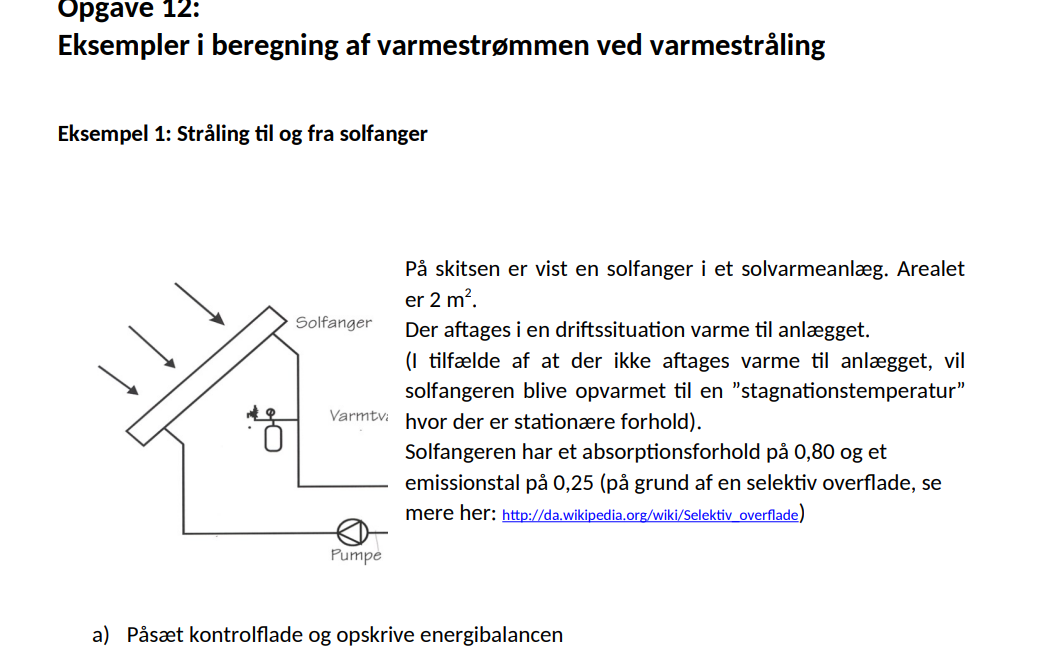

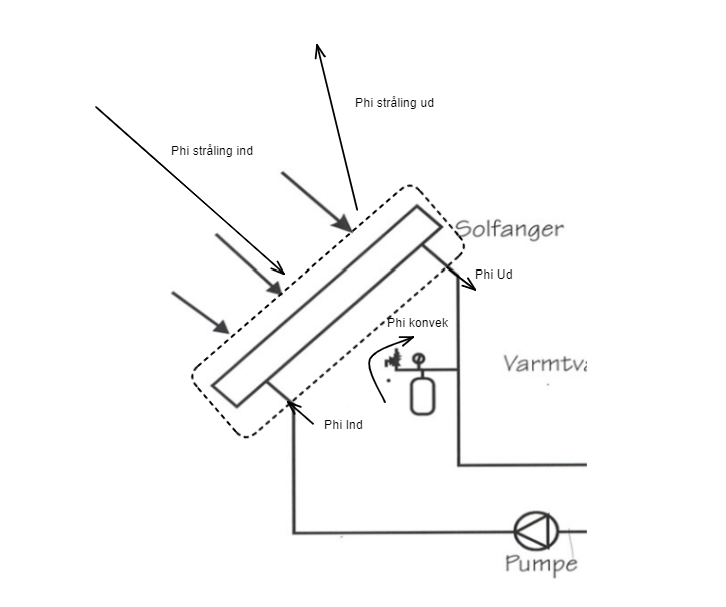


$$\Phi_{sol} - (\Phi_{Konvek} + \Phi_{Maskin} + \Phi_{Udstr\aa ling})$$


positiv sol ind, negativ alt andet da alt andet køler ned og solen opheder (eller solen tilføjet energi og andet trækker energi ud) 

u = symunit;
Phi_sol = 800 * u.W/u.m^2 * 2 * u.m^2 * 0.8 % 80 procent bliver absoberet, 20 procent bliver reflekteret. 800w/m^2 over 2 m^2 

$$Phi\_sol = 1280\,W$$

Epsilon = 0.25

Epsilon = 0.2500

Cs = 5.67 * u.W/(u.m^2*u.K^4)

$$Cs = \frac{567}{100}\,\frac{W}{K^{4}\,m^{2}}$$

T = convtemp(80, "C", "K") * u.K

$$T = \frac{7063}{20}\,K$$

T2 = convtemp(20, "C", "K") * u.K

$$T2 = \frac{5863}{20}\,K$$


phi_udstroling = vpa(Epsilon * Cs * 2*u.m^2 * (T/100)^4 , 4)

$$phi\_udstroling = 441.0\,W$$

alpha_konvek = 4 * u.W/(u.m^2*u.K)

$$alpha\_konvek = 4\,\frac{W}{K\,m^{2}}$$

tveg = convtemp(80, "C", "K") * u.K

$$tveg = \frac{7063}{20}\,K$$

A = 2 * u.m^2

$$A = 2\,m^{2}$$

Phi_konvek = alpha_konvek * A * (tveg - T2) %T2 er luft temperatur

$$Phi\_konvek = 480\,W$$

syms phi_maskin
phi_maskin = vpa(solve(Phi_sol - (phi_maskin + phi_udstroling + Phi_konvek) == 0, phi_maskin), 4) %%løser bare for energi ligningen

$$phi\_maskin = 359.0\,W$$

ans = 0.2244